rng(14);
n=50;
rand1 = normrnd(0.3,0.1,[1,floor(n/3)]);
rand3 = gamrnd(.5,0.5,[1,floor(n/3)]);
rand4 = normrnd(0.7,0.01,[1,ceil(n/3)]);

y = ([rand1,rand3,rand4])

y =     0.3073    0.4000    0.3968    0.2122    0.2618    0.3954    0.3032    0.2525    0.3126    0.1953    0.3979    0.2654    0.3232    0.2119    0.3361    0.2314    0.1291    0.2038    0.2110    0.3912    0.3363    0.0088    0.2278    0.2570    0.0003    0.0423    0.2716    0.0039    0.0301    0.3446    0.0364    0.0938    0.7081    0.6899    0.6918    0.6839    0.7003    0.7029    0.7028    0.6881    0.6982    0.6987    0.6888    0.7009    0.6964    0.6797    0.7113    0.6884    0.7053


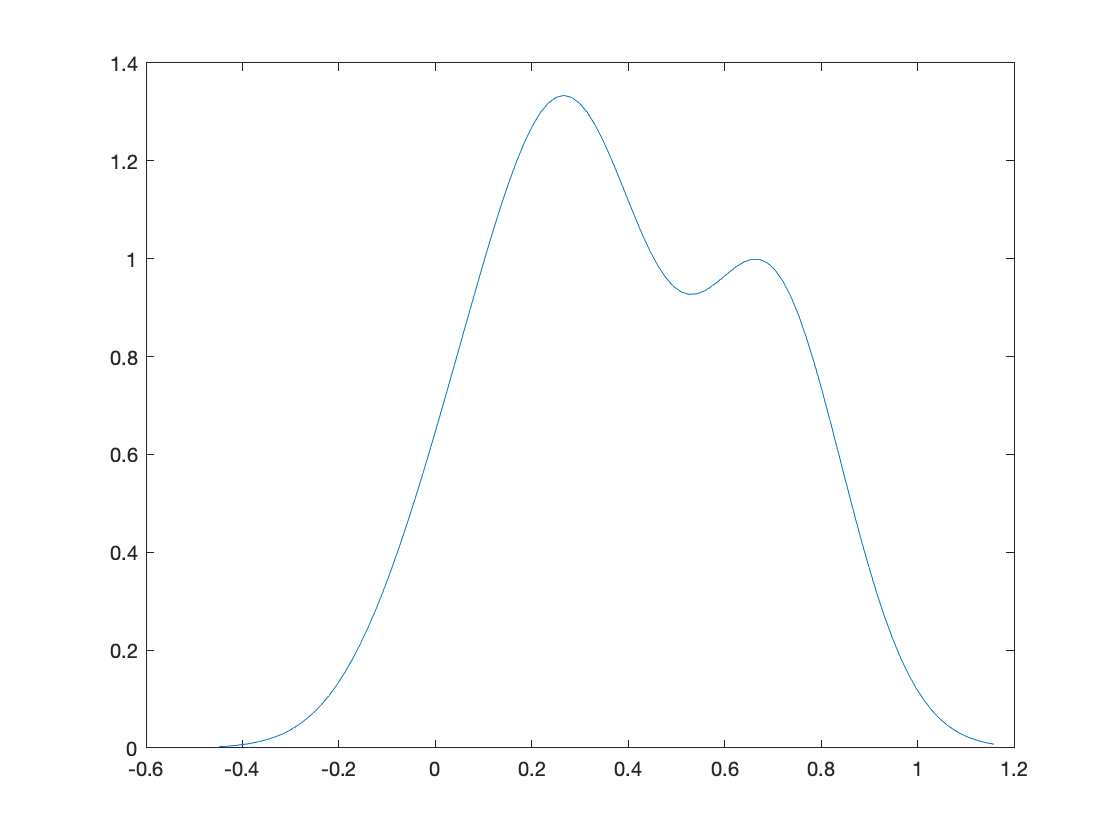

[f,yi] = ksdensity(y);
plot(yi,f)


sum(y<0)

ans = 0

sum(y>1)

ans = 0


knots = [0.0, 0.1, 0.21, 0.41, 0.6, 0.81, 1];
d = 5;
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);
tol=1e-6;

flag=1;
solve_this = @(a) (constraintFunc(a));
initial = 1:d

initial =      1     2     3     4     5


initial_guess = fsolve(solve_this, initial.*0.01, options);

num_iters = 20000;
burn_in = 5000;
proposal_scale = 0.01

proposal_scale = 0.0100


ll_function = @(x) ll_density(x, knots, y);
constraintFunc = @(x) logspline_constraint(knots, x);
dConstraintFunc = @(x) dlogspline_constraint(knots, x);
[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess', ll_function, ...
    constraintFunc, dConstraintFunc)

Output argument "ll" (and maybe others) not assigned during call to "ll_density".

Error in CMH_logsplines (line 28)
ll_function = @(x) ll_density(x, knots, y);

Error in runConstrainedMH (line 33)
        MH_ratio = ll_function(proposal) + log(prob_reverse) - ...

mean(accepts)
save("MH_sphereDraws.mat",'samples');

samples=load("MH_sphereDraws.mat");
xs=real(samples.samples(1,:))';
ys=real(samples.samples(2,:))';
zs=real(samples.samples(3,:))';
dim=size(xs);
plot3(xs,ys,zs,'-o','Color','r','MarkerSize',2,'MarkerFaceColor','#D9FFFF')
hold on
theta=linspace(0,2*pi,40);
phi=linspace(0,pi,40);
[theta,phi]=meshgrid(theta,phi);
rho=1;
x=rho*sin(phi).*cos(theta);
y=rho*sin(phi).*sin(theta);
z=rho*(cos(phi)+z_shift);
mesh(x,y,z,'EdgeColor',[0.3010 0.7450 0.9330],'FaceAlpha',.3)
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
hold off

thetas_unshifted=atan(ys./xs);
theta_draws=thetas_unshifted+pi*(xs<0)+...
    2*pi*(xs>0&ys<0);
theta_draws(isnan(theta_draws))=0;
phi_draws=acos(zs-z_shift);

[n,d]=size(theta);
dens2=zeros(n,d);
for t=2:n
    for p=2:d
        x_in= (theta_draws>=theta(p,t-1))&(theta_draws<theta(p,t));
        y_in= (phi_draws>=phi(p-1,t))&(phi_draws<phi(p,t));
        dens2(p,t)=mean(x_in&y_in)*sin(phi(p-1,t-1));
    end
end
s2=surf(x,y,z);
s2.CData=dens2;
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
colorbar
view([-47.19 17.56])
% h = colorbar;
% set(h, 'ylim', [0 0.45])
% hold on
% % plot3(m1-0.05,m2+0.05,m3+0.05,'.','Color','r','MarkerSize',60)
% hold off